## Задание 2. Управление по выходу с заданной степенью устойчивости.  

Начальные условия на задание:

A = [5 -7 -5 1;
    -7 5 -1 5;
    -5 -1 5 7;
    1 5 7 5]

A =      5    -7    -5     1
    -7     5    -1     5
    -5    -1     5     7
     1     5     7     5


B = [5 7 1 9]'

B =      5
     7
     1
     9



C = [ 0 0 2 2;
     1 1 -1 -1]

C =      0     0     2     2
     1     1    -1    -1


Какая система будет то?

U = [B , A*B , A^2 * B, A^3 * B];
U = ctrb(A, B);
rank(U)

ans = 4


V = obsv(A, C)

V =            0           0           2           2
           1           1          -1          -1
          -8           8          24          24
           2          -6         -18          -6
        -192         192         320         320
         136         -56        -136        -184
       -3584        3584        4608        4608
        1568       -2016       -2592       -2016


V = [C ; C*A ; C*A^2 ; C*A^3];
rank(V)

ans = 4

**Управляемая + стабилизируема**

**Наблюдаема+обнаруживаема**

Проверка критерия Хаутуса:

eig(A)

ans =    -8.0000
    4.0000
    8.0000
   16.0000


Максимум сможем добиться любой степени устойчивости, поскольку система управляема и при помощи регулятора мы можем сдвинуть все собственные числа куда угодно. 

(степень устойчивости определена для изначально устойчивой системы)

l1 = -8; l2 = 4; l3 = 8; l4 = 16;

[A - eye(4).*l1 , B]

ans =     13    -7    -5     1     5
    -7    13    -1     5     7
    -5    -1    13     7     1
     1     5     7    13     9


[A - eye(4).*l2 , B]

ans =      1    -7    -5     1     5
    -7     1    -1     5     7
    -5    -1     1     7     1
     1     5     7     1     9


[A - eye(4).*l3 , B]

ans =     -3    -7    -5     1     5
    -7    -3    -1     5     7
    -5    -1    -3     7     1
     1     5     7    -3     9


[A - eye(4).*l4 , B]

ans =    -11    -7    -5     1     5
    -7   -11    -1     5     7
    -5    -1   -11     7     1
     1     5     7   -11     9



rank([A - eye(4).*l1 , B])

ans = 4

rank([A - eye(4).*l2 , B])

ans = 4

rank([A - eye(4).*l3 , B])

ans = 4

rank([A - eye(4).*l4 , B])

ans = 4

В начале тут была попытка найти матрицы коррекции и матрицы регуляторов при помощи LMI, но собственные числа не очень хорошо сблизились, пробую через Риккати с Q=0 теперь....

nu = 2; R = 1;

## Выбрать несколько alpha, которые мы будем перебирать между наблюдателем и контроллером

alpha = 3; alpha = 11;

x0 = [1 1 1 1]';        % plant
x_hat0 = [0 0 0 0]';   % observer
simTimeStart = 0;
simTimeEnd = 5;
step = 0.0001; 
time = (simTimeStart:step:simTimeEnd)';

data.time= time;
modelName = 'model_observer_controller'; 
load_system(modelName);

Рассмотрим некоторые комбинации коэффициентов для наблюдателя и регулятора

### alpha_K == alpha_L

alpha_K = 3

alpha_K = 3

alpha_L = 3

alpha_L = 3

Метод LMI ...

% %%% Synthesize CTRL %%%
% % solving LMI
% Q = eye(4);
% cvx_begin sdp
% variable P(4,4)
% % variable Y(1,4)
% variable mumu; minimize mumu; % = mu^2
% P > 0.0001*eye(4);
% % P*A' + A*P + 2*alpha*P +Y'*B' + B*Y <=0; % worked bad...
% 
% A'*P +P*A -2*P*B*R^-1 * B'*P + 2*alpha*P + Q == 0;
% [P x0; x0' 1;] > 0;
% [P Y'; Y mumu] > 0;
% cvx_end
% u_min = sqrt(mumu)
% K = -R^-1 * B' * P
% eig(A + B * K) 
% %%% Synthesize OBSV %%%
% e0 = x0 - x_hat0; % initial error !
% % solving LMI
% cvx_begin sdp
% variable Q(4,4)
% variable Y(4,2)
% variable mumu; minimize mumu; % = mu^2
% Q > 0.0001*eye(4);
% A'*Q + Q*A + 2*alpha*Q + C'*Y' + Y*C <=0 ;
% 
% [Q e0; e0' 1;] > 0;
% [Q Y; Y' [mumu 0; 0 mumu]] > 0;
% cvx_end
% 
% L = inv(Q)*Y
% mu = sqrt(mumu)
% eig(A + L*C)
% %%%___________%%%

Метод Риккати

% %%% Synthesize CTRL %%%
% Q = zeros([4 4])
Q = eye(4)

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Aa = A + eye(4)*alpha_K;
[P, ~, EIG1] = icare(Aa, sqrt(nu)*B, Q, R);
K = -inv(R) * B' * P

K =    48.6380  -60.4377   24.3658   12.5582


mat2tex(K,2);

\begin{bmatrix}
    48.64 & -60.44 & 24.37 & 12.56 \\
\end{bmatrix}


EIG_K =  eig(A + B * K)

EIG_K =   -4.8320 +23.7472i
  -4.8320 -23.7472i
  -7.9799 + 0.0000i
  -4.8409 + 0.0000i


% %%% Synthesize OBSV %%%
Aa = A + eye(4)*alpha_L;
[P, ~, EIG1] = icare(Aa, sqrt(nu)*C', Q, R);
L = -P*C'*inv(R)

L =    20.4725  -17.4418
  -23.7233   10.1658
   -4.7371    6.0231
   -8.0083   -1.2758


mat2tex(L,2);

\begin{bmatrix}
    20.47 & -17.44 \\
    -23.72 & 10.17 \\
    -4.74 & 6.02 \\
    -8.01 & -1.28 \\
\end{bmatrix}


EIG_K =  eig(A + L * C)

EIG_K =   -3.1859 +14.6873i
  -3.1859 -14.6873i
  -7.9697 + 0.0000i
  -3.1728 + 0.0000i


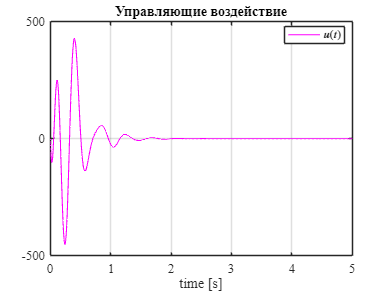


out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;


u = out.u.Data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0);
grid on;
xlabel('time [s]');
grid on;
title('Управляющие воздействие')
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("obsv_u1");

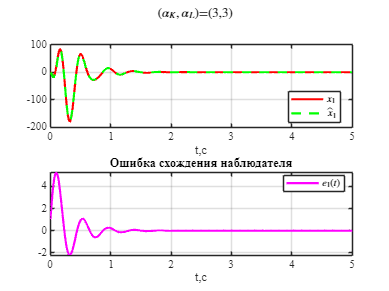


h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_1(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(3,3)','Interpreter','latex')
save_file("obsv1");

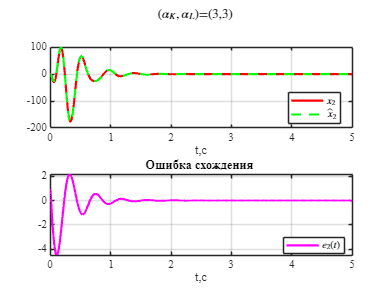

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения ')
xlabel('t,c'); ylabel(' ') ;
legend('$e_2(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(3,3)','Interpreter','latex')
save_file("obsv2");

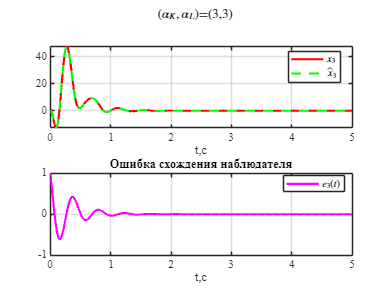

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,3), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,3),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{3}$','$\hat{x}_{3}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,3),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_3(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(3,3)','Interpreter','latex')
save_file("obsv3");

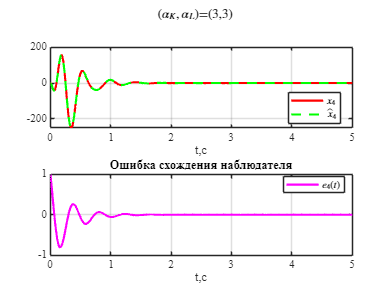

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,4), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,4),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{4}$','$\hat{x}_{4}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,4),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_4(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(3,3)','Interpreter','latex')
save_file("obsv4");

%%%%%%%%%%%%%%

alpha_K = 11

alpha_K = 11

alpha_L = 11

alpha_L = 11


% %%% Synthesize CTRL %%%
% % solving LMI
% cvx_begin sdp
% variable P(4,4)
% variable Y(1,4)
% variable mumu; minimize mumu; % = mu^2
% P > 0.0001*eye(4);
% P*A' + A*P + 2*alpha*P +Y'*B' + B*Y <=0;
% [P x0; x0' 1;] > 0;
% [P Y'; Y mumu] > 0;
% cvx_end
% u_min = sqrt(mumu)
% K = Y*inv(P)
% eig(A + B * K) 
% %%% Synthesize OBSV %%%
% e0 = x0 - x_hat0; % initial error !
% % solving LMI
% cvx_begin sdp
% variable Q(4,4)
% variable Y(4,2)
% variable mumu; minimize mumu; % = mu^2
% Q > 0.0001*eye(4);
% A'*Q + Q*A + 2*alpha*Q + C'*Y' + Y*C <=0 ;
% 
% [Q e0; e0' 1;] > 0;
% [Q Y; Y' [mumu 0; 0 mumu]] > 0;
% cvx_end
% 
% L = inv(Q)*Y
% mu = sqrt(mumu)
% eig(A + L*C)
% %%%___________%%%

% %%% Synthesize CTRL %%%
% Q = zeros([4 4])
Q = eye(4)

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Aa = A + eye(4)*alpha_K;
[P, ~, EIG1] = icare(Aa, sqrt(nu)*B, Q, R);
K = -inv(R) * B' * P

K =   225.1388 -304.3696  175.4919   84.6039


mat2tex(K,2);

\begin{bmatrix}
    225.14 & -304.37 & 175.49 & 84.6 \\
\end{bmatrix}


EIG_K =  eig(A + B * K)

EIG_K =  -12.1492 +39.3978i
 -12.1492 -39.3978i
 -11.8339 + 4.4191i
 -11.8339 - 4.4191i


% %%% Synthesize OBSV %%%
Aa = A + eye(4)*alpha_L;
[P, ~, EIG1] = icare(Aa, sqrt(nu)*C', Q, R);
L = -P*C'*inv(R)

L =    50.5187  -35.8935
  -60.2005   18.5075
   -1.9378   14.7957
  -18.8086   -9.2633


mat2tex(L,2);

\begin{bmatrix}
    50.52 & -35.89 \\
    -60.2 & 18.51 \\
    -1.94 & 14.8 \\
    -18.81 & -9.26 \\
\end{bmatrix}


EIG_K =  eig(A + L * C)

EIG_K =  -11.0909 + 6.2774i
 -11.0909 - 6.2774i
 -11.1147 +23.2056i
 -11.1147 -23.2056i


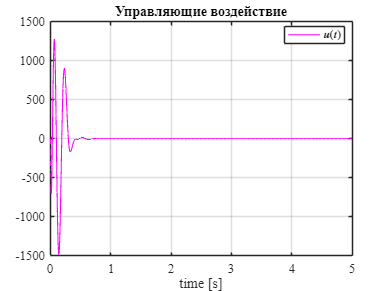

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;

u = out.u.Data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0);
grid on;
xlabel('time [s]');
grid on;
title('Управляющие воздействие')
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("obsv_u2");

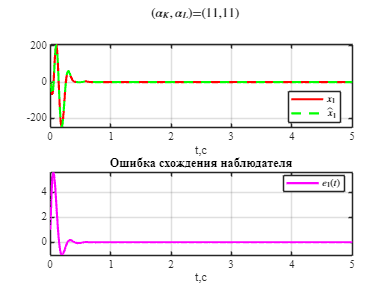


h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_1(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(11,11)','Interpreter','latex')
save_file("obsv5");

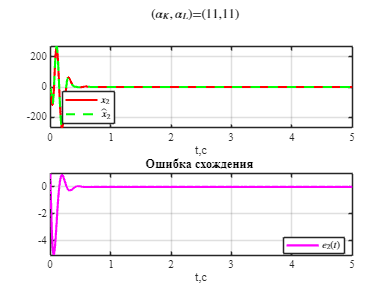

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения ')
xlabel('t,c'); ylabel(' ') ;
legend('$e_2(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(11,11)','Interpreter','latex')
save_file("obsv6");

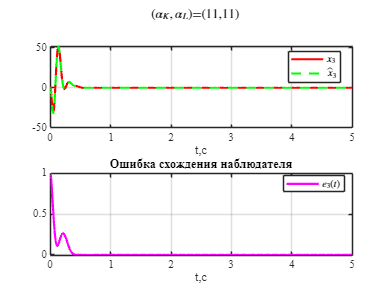

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,3), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,3),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{3}$','$\hat{x}_{3}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,3),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_3(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(11,11)','Interpreter','latex')
save_file("obsv7");

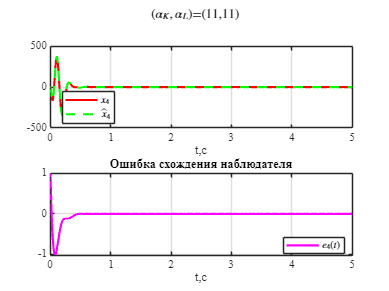

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,4), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,4),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{4}$','$\hat{x}_{4}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,4),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_4(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(11,11)','Interpreter','latex')
save_file("obsv8");

%%%%%%%%%%%%%%

### alpha_K > alpha_L

alpha_K = 11 

alpha_K = 11

alpha_L = 3

alpha_L = 3

% %%% Synthesize CTRL %%%
% % solving LMI
% cvx_begin sdp
% variable P(4,4)
% variable Y(1,4)
% variable mumu; minimize mumu; % = mu^2
% P > 0.0001*eye(4);
% P*A' + A*P + 2*alpha_K*P +Y'*B' + B*Y <=0;
% [P x0; x0' 1;] > 0;
% [P Y'; Y mumu] > 0;
% cvx_end
% u_min = sqrt(mumu)
% K = Y*inv(P)
% eig(A + B * K) 
% %%% Synthesize OBSV %%%
% e0 = x0 - x_hat0; % initial error !
% % solving LMI
% cvx_begin sdp
% variable Q(4,4)
% variable Y(4,2)
% variable mumu; minimize mumu; % = mu^2
% Q > 0.0001*eye(4);
% A'*Q + Q*A + 2*alpha_L*Q + C'*Y' + Y*C <=0 ;
% 
% [Q e0; e0' 1;] > 0;
% [Q Y; Y' [mumu 0; 0 mumu]] > 0;
% cvx_end
% 
% L = inv(Q)*Y
% mu = sqrt(mumu)
% eig(A + L*C)
% %%%___________%%%

% %%% Synthesize CTRL %%%
% Q = zeros([4 4])
Q = eye(4)

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Aa = A + eye(4)*alpha_K;
[P, ~, EIG1] = icare(Aa, sqrt(nu)*B, Q, R);
K = -inv(R) * B' * P

K =   225.1388 -304.3696  175.4919   84.6039


mat2tex(K,2);

\begin{bmatrix}
    225.14 & -304.37 & 175.49 & 84.6 \\
\end{bmatrix}


EIG_K =  eig(A + B * K)

EIG_K =  -12.1492 +39.3978i
 -12.1492 -39.3978i
 -11.8339 + 4.4191i
 -11.8339 - 4.4191i


% %%% Synthesize OBSV %%%
Aa = A + eye(4)*alpha_L;
[P, ~, EIG1] = icare(Aa, sqrt(nu)*C', Q, R);
L = -P*C'*inv(R)

L =    20.4725  -17.4418
  -23.7233   10.1658
   -4.7371    6.0231
   -8.0083   -1.2758


mat2tex(L,2);

\begin{bmatrix}
    20.47 & -17.44 \\
    -23.72 & 10.17 \\
    -4.74 & 6.02 \\
    -8.01 & -1.28 \\
\end{bmatrix}


EIG_K =  eig(A + L * C)

EIG_K =   -3.1859 +14.6873i
  -3.1859 -14.6873i
  -7.9697 + 0.0000i
  -3.1728 + 0.0000i


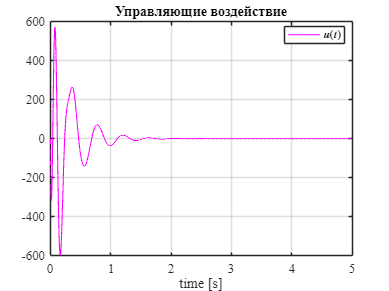

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;

u = out.u.Data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0);
grid on;
xlabel('time [s]');
grid on;
title('Управляющие воздействие')
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("obsv_u3");

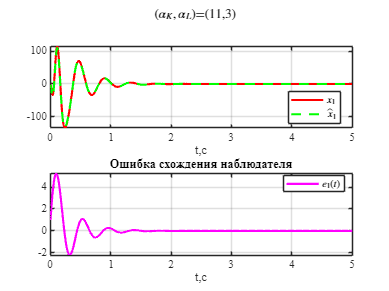


h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_1(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(11,3)','Interpreter','latex')
save_file("obsv9");

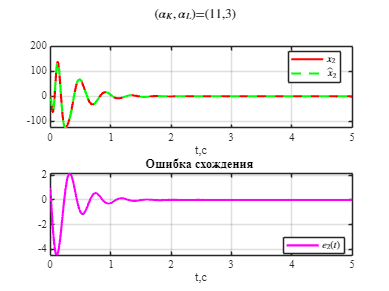

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения ')
xlabel('t,c'); ylabel(' ') ;
legend('$e_2(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(11,3)','Interpreter','latex')
save_file("obsv10");

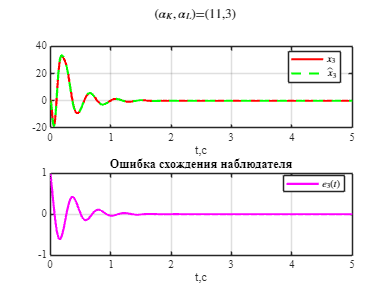

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,3), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,3),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{3}$','$\hat{x}_{3}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,3),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_3(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(11,3)','Interpreter','latex')
save_file("obsv11");

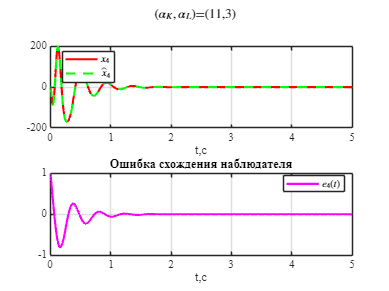

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,4), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,4),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{4}$','$\hat{x}_{4}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,4),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_4(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(11,3)','Interpreter','latex')
save_file("obsv12");

%%%%%%%%%%%%%%

### alpha_K < alpha_L

alpha_K = 3

alpha_K = 3

alpha_L = 11

alpha_L = 11

% %%% Synthesize CTRL %%%
% % solving LMI
% cvx_begin sdp
% variable P(4,4)
% variable Y(1,4)
% variable mumu; minimize mumu; % = mu^2
% P > 0.0001*eye(4);
% P*A' + A*P + 2*alpha_K*P +Y'*B' + B*Y <=0;
% [P x0; x0' 1;] > 0;
% [P Y'; Y mumu] > 0;
% cvx_end
% u_min = sqrt(mumu)
% K = Y*inv(P)
% eig(A + B * K) 
% %%% Synthesize OBSV %%%
% e0 = x0 - x_hat0; % initial error !
% % solving LMI
% cvx_begin sdp
% variable Q(4,4)
% variable Y(4,2)
% variable mumu; minimize mumu; % = mu^2
% Q > 0.0001*eye(4);
% A'*Q + Q*A + 2*alpha_L*Q + C'*Y' + Y*C <=0 ;
% 
% [Q e0; e0' 1;] > 0;
% [Q Y; Y' [mumu 0; 0 mumu]] > 0;
% cvx_end
% 
% L = inv(Q)*Y
% mu = sqrt(mumu)
% eig(A + L*C)
% %%%___________%%%

% %%% Synthesize CTRL %%%
% Q = zeros([4 4])
Q = eye(4)

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Aa = A + eye(4)*alpha_K;
[P, ~, EIG1] = icare(Aa, sqrt(nu)*B, Q, R);
K = -inv(R) * B' * P

K =    48.6380  -60.4377   24.3658   12.5582


mat2tex(K,2);

\begin{bmatrix}
    48.64 & -60.44 & 24.37 & 12.56 \\
\end{bmatrix}


EIG_K =  eig(A + B * K)

EIG_K =   -4.8320 +23.7472i
  -4.8320 -23.7472i
  -7.9799 + 0.0000i
  -4.8409 + 0.0000i


% %%% Synthesize OBSV %%%
Aa = A + eye(4)*alpha_L;
[P, ~, EIG1] = icare(Aa, sqrt(nu)*C', Q, R);
L = -P*C'*inv(R)

L =    50.5187  -35.8935
  -60.2005   18.5075
   -1.9378   14.7957
  -18.8086   -9.2633


mat2tex(L,2);

\begin{bmatrix}
    50.52 & -35.89 \\
    -60.2 & 18.51 \\
    -1.94 & 14.8 \\
    -18.81 & -9.26 \\
\end{bmatrix}


EIG_K =  eig(A + L * C)

EIG_K =  -11.0909 + 6.2774i
 -11.0909 - 6.2774i
 -11.1147 +23.2056i
 -11.1147 -23.2056i


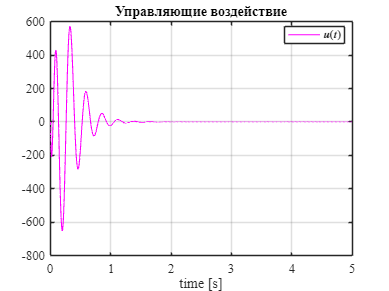

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;


u = out.u.Data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0);
grid on;
xlabel('time [s]');
grid on;
title('Управляющие воздействие')
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("obsv_u4");

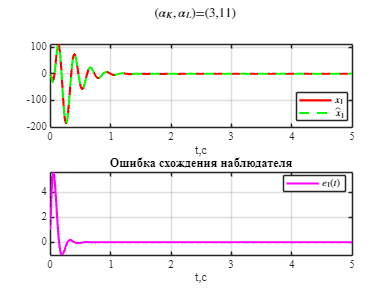


h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_1(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(3,11)','Interpreter','latex')
save_file("obsv13");

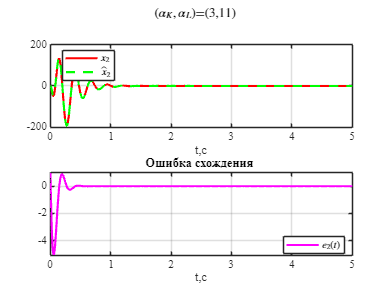

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения ')
xlabel('t,c'); ylabel(' ') ;
legend('$e_2(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(3,11)','Interpreter','latex')
save_file("obsv14");

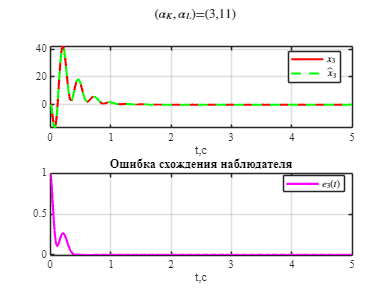

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,3), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,3),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{3}$','$\hat{x}_{3}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,3),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_3(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(3,11)','Interpreter','latex')
save_file("obsv15");

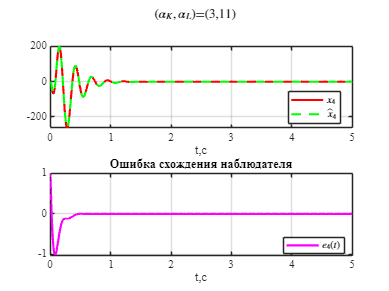

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,4), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,4),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{4}$','$\hat{x}_{4}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,4),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_4(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha_K, \alpha_L)$=(3,11)','Interpreter','latex')
save_file("obsv16");

%%%%%%%%%%%%%%


**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab9\latex9\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end

function latexMatrix = mat2tex(A, precision)
    % Проверка, что A - это матрица
    if ~ismatrix(A)
        error('Input must be a matrix.');
    end
    
    % Проверка, что precision - положительное целое число
    if ~isscalar(precision) || precision < 1 || floor(precision) ~= precision
        error('Precision must be a positive integer.');
    end

    % Начало LaTeX-кода с окружением bmatrix (квадратные скобки)
    lines = ["\begin{bmatrix}"];

    % Формирование строк матрицы
    for i = 1:size(A,1)
        rowElements = strings(1, size(A,2)); % Создаём строку строк для LaTeX
        for j = 1:size(A,2)
            elem = A(i,j);
            if isreal(elem)
                % Округляем число с нужной точностью
                roundedElem = round(elem, precision);
                
                % Проверка, является ли число целым (первые precision знаков после запятой - нули)
                if mod(roundedElem, 1) == 0
                    rowElements(j) = sprintf('%d', roundedElem);
                else
                    % Форматирование дробного числа с нужным precision
                    roundedElem = round(elem, precision);
                    rowElements(j) = regexprep(sprintf('%.*f', precision, roundedElem), '0+$', '');
                    rowElements(j) = regexprep(rowElements(j), '\.$', ''); % Убираем лишнюю точку, если осталась
                end
            else
                % Если элемент комплексный, разбираем его на части
                realPart = real(elem);
                imagPart = imag(elem);

                % Округляем обе части
                realPart = round(realPart, precision);
                imagPart = round(imagPart, precision);

                % Проверка, является ли действительная часть целым числом
                if mod(realPart, 1) == 0
                    realStr = sprintf('%d', realPart);
                else
                    realPart = round(realPart, precision);
                    realStr = regexprep(sprintf('%.*f', precision, realPart), '0+$', '');
                    realStr = regexprep(realStr, '\.$', '');
                end

                % Проверка, является ли мнимая часть целым числом
                if mod(imagPart, 1) == 0
                    imagStr = sprintf('%d', imagPart);
                else
                    imagPart = round(imagPart, precision);
                    imagStr = regexprep(sprintf('%.*f', precision, imagPart), '0+$', '');
                    imagStr = regexprep(imagStr, '\.$', '');
                end

                if realPart == 0
                    % Только мнимая часть
                    rowElements(j) = sprintf('%si', imagStr);
                elseif imagPart == 0
                    % Только действительная часть
                    rowElements(j) = realStr;
                else
                    % Полное комплексное число с правильными знаками
                    signChar = ' + ';
                    if imagPart < 0
                        signChar = ' - ';
                        imagStr = erase(imagStr, '-'); % Убираем минус, так как он уже указан
                    end
                    rowElements(j) = sprintf('%s%s%si', realStr, signChar, imagStr);
                end
            end
        end
        % Объединяем строку с `&` и добавляем её в LaTeX-матрицу
        lines = [lines; "    " + strjoin(rowElements, ' & ') + " \\"]; 
    end

    % Завершение окружения bmatrix
    lines = [lines; "\end{bmatrix}"];

    % Соединяем все строки без добавления `\n`
    latexMatrix = join(lines, newline);

    % Выводим отформатированную строку в командное окно
    disp(latexMatrix);
end
